# Leo Berman & Justin Ok Project 4 Code

## Step 0

% Load in data
clear;
data = load("ecg_data.txt");
t = data(:,1);
x = data(:,2);
fs = 1000;

## Step 1

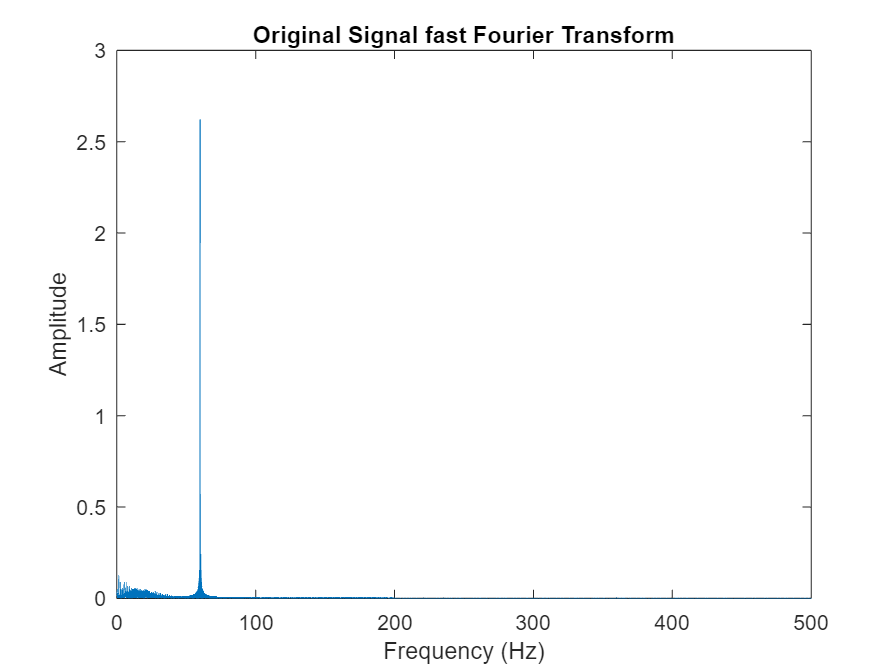

% Examine Fourier Transform and original signal
myFFT(x,fs);
title('Original Signal fast Fourier Transform')
hold off

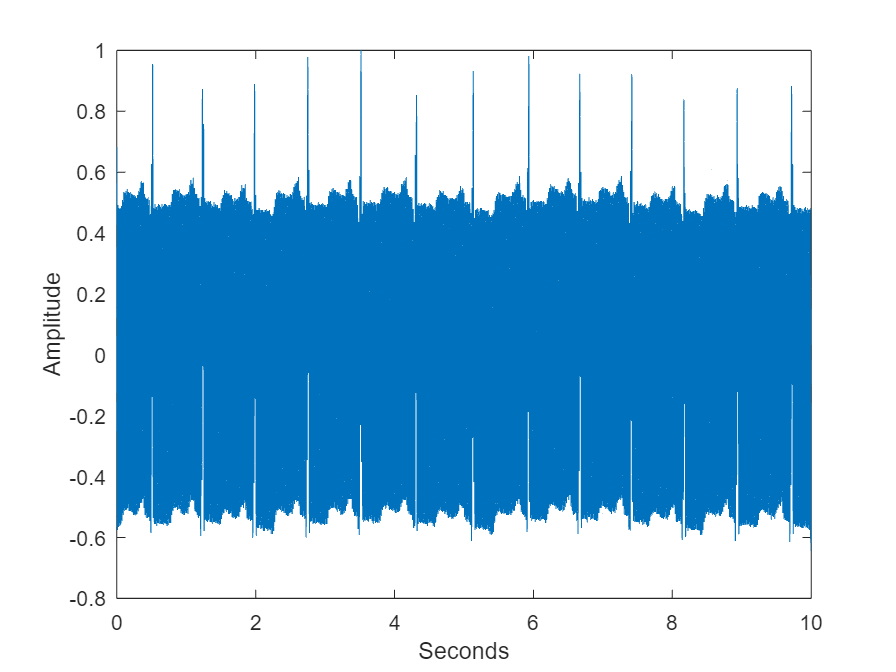

plot(t,x)
xlabel('Seconds')
ylabel('Amplitude')
hold off

## Step 2

### RC Low Pass Filter

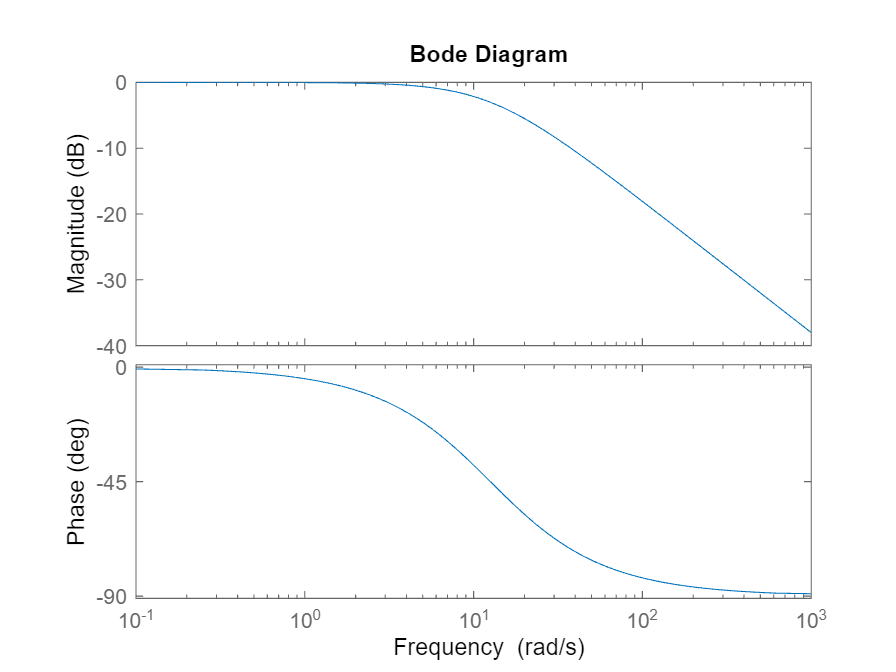

% Load in component values
R = 1/(4*pi);
C = 1;
syms s
Zr = R;
Zc = 1/(s*C);
% Find the transfer function
Vout = simplify((Zc/(Zr+Zc)));
[num,den] = numden(Vout);
zeroth = subs(den,s,0);
first = double(((den-zeroth)/s)/zeroth);
Hf = tf(1,[first 1]);
% Plot the bode
bodeplot(Hf)

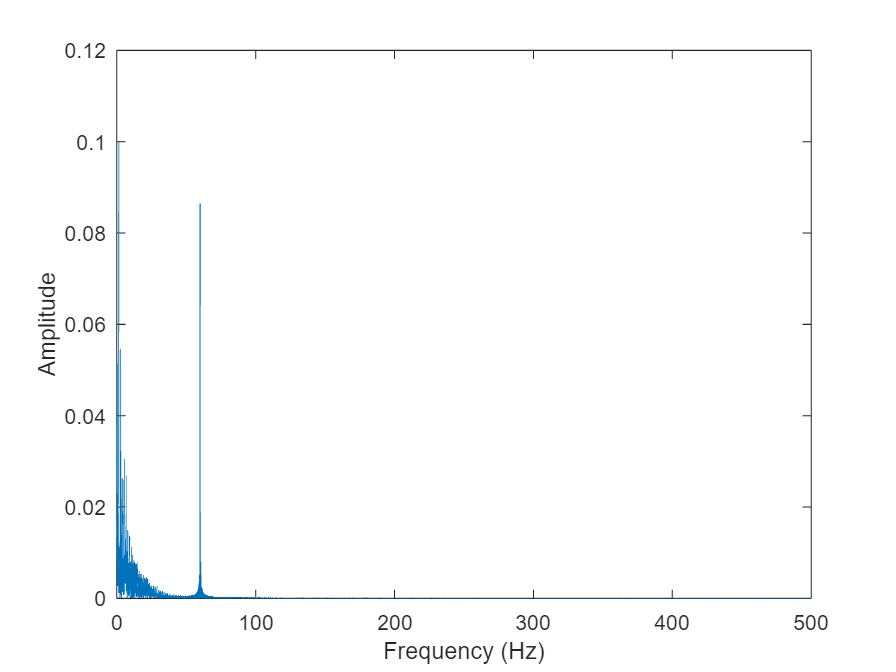

% Put the signal through the transfer function
RCFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(RCFilteredSignal,fs)
hold off

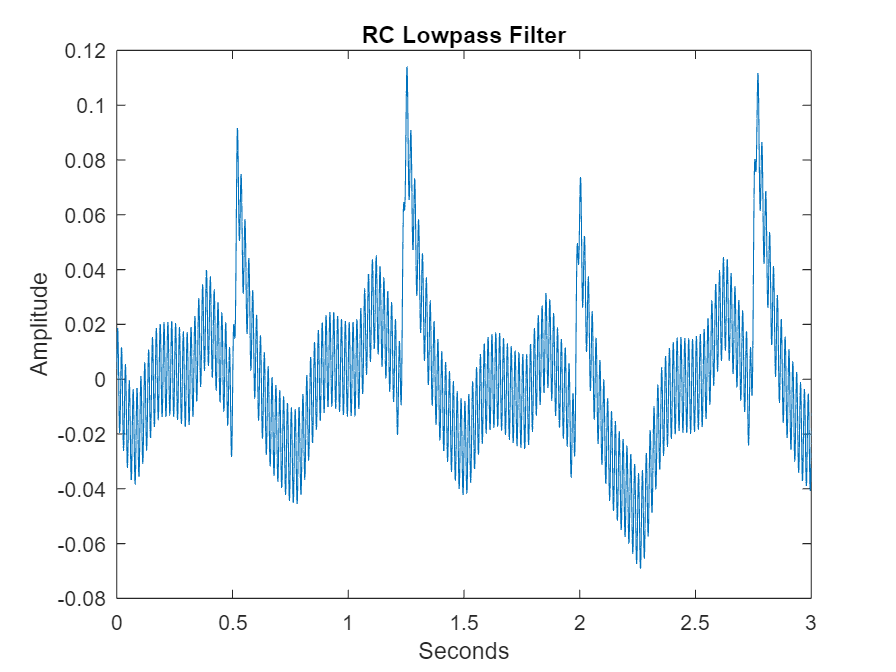

% Plot the filtered signal
plot(t,RCFilteredSignal)
xlim([0,3])
title('RC Lowpass Filter')
xlabel('Seconds')
ylabel('Amplitude')
hold off

### RLC Band Stop Filter

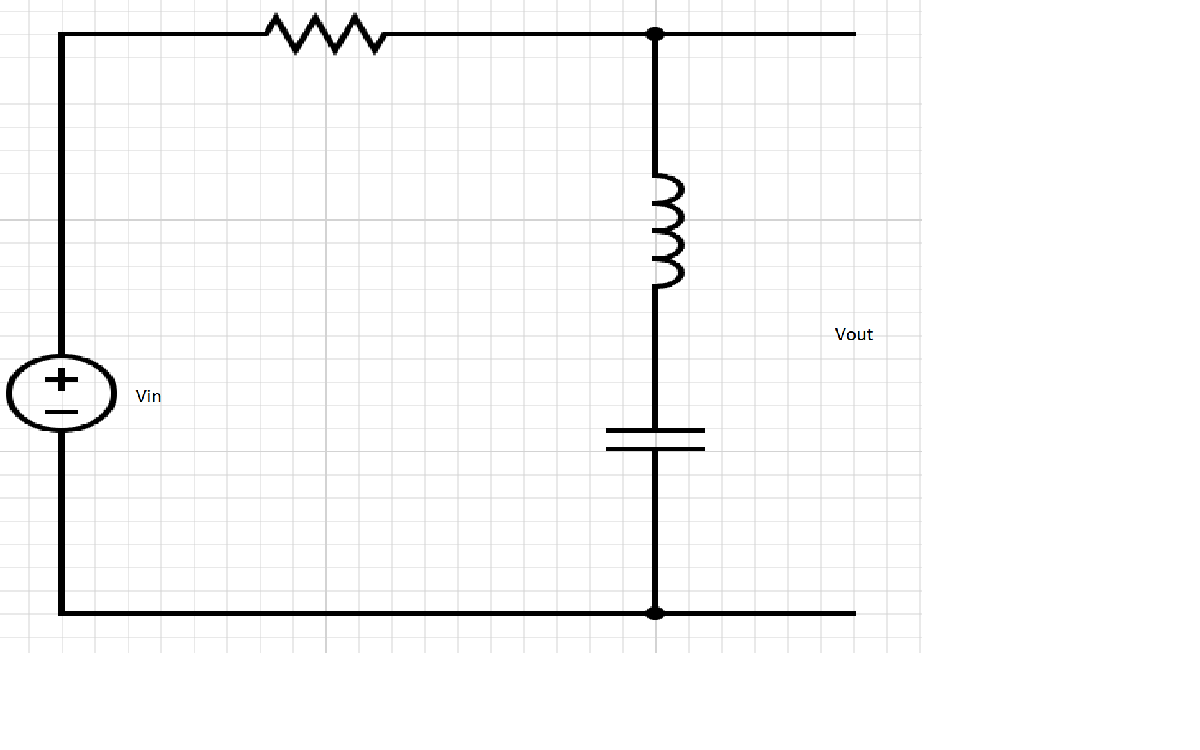

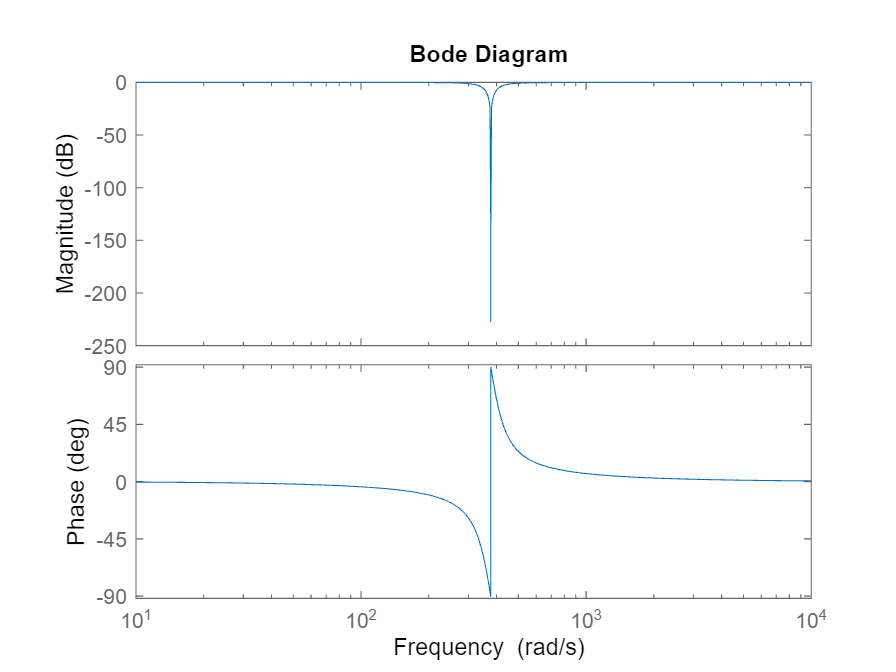

%% 1.5 Hz Width Stop Filter
% Load component values
R = 1.5*2*pi;
L = 1;
C = 1/((120*pi)^2);
% Find the transfer function
syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vout = simplify(((Zl+Zc))/(Zr+Zl+Zc));
Hf = tf([L/((1/C)) 0 1],[L/((1/C)) (R*10)/((1/C)) 1]);
% Plot the bode
bodeplot(Hf)

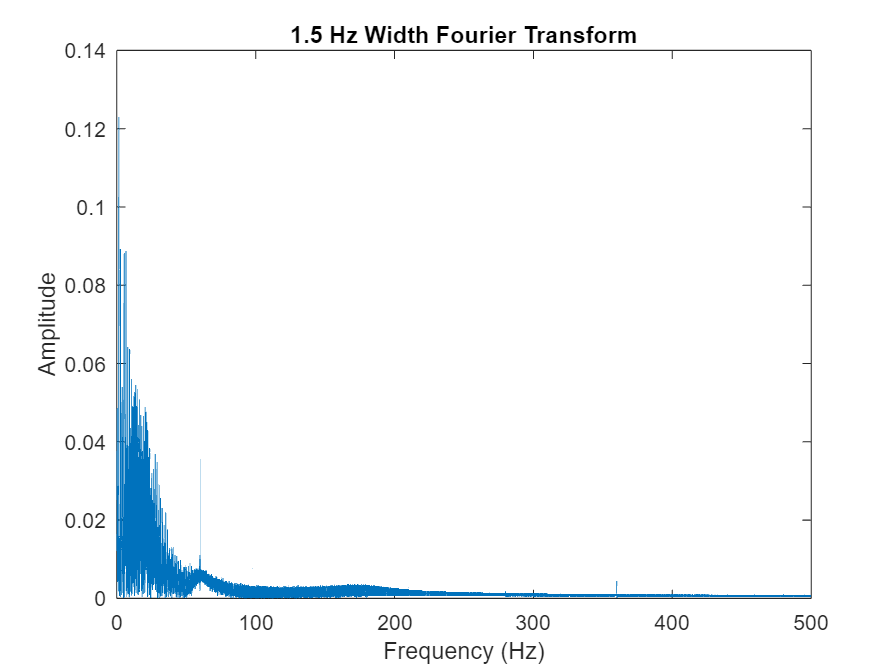

% Filter the signal
RLCStopFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(RLCStopFilteredSignal,fs)
title('1.5 Hz Width Fourier Transform')
hold off

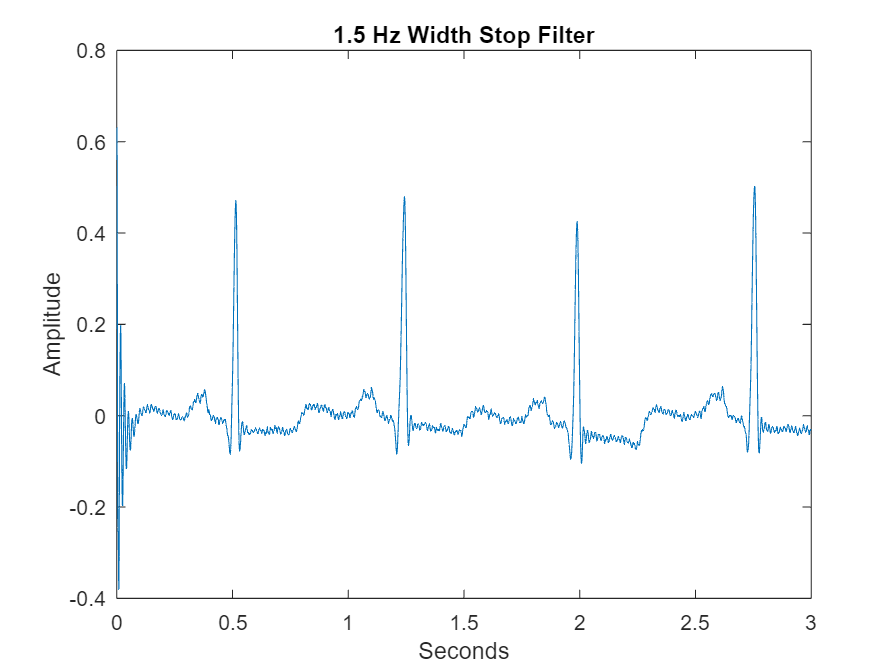

% Plot the filtered signal
plot(t,RLCStopFilteredSignal)
xlim([0,3])
title('1.5 Hz Width Stop Filter')
xlabel('Seconds')
ylabel('Amplitude')
hold off

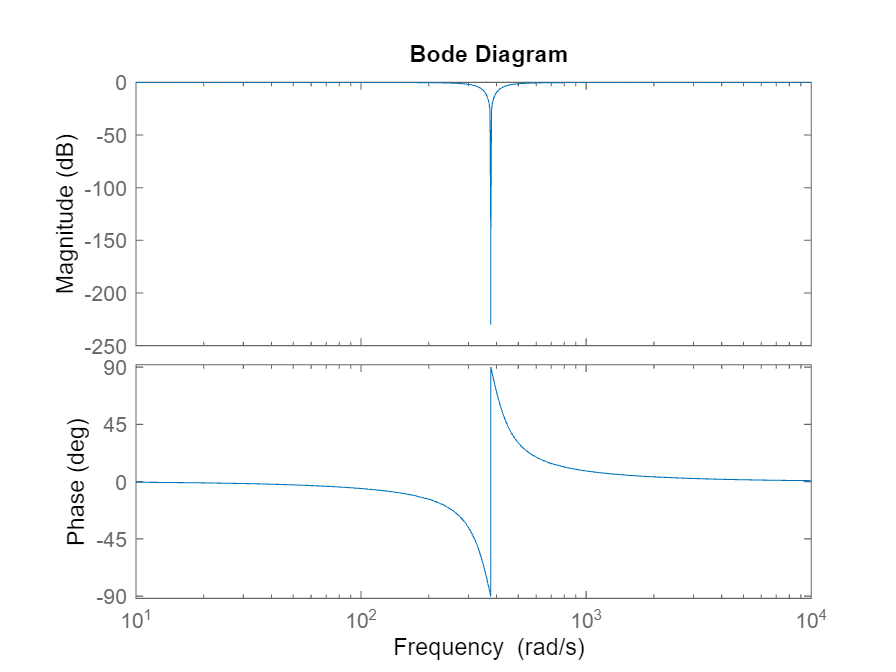

%% 2 Hz Width Stop Filter
% Load component values
R = 2*2*pi;
L = 1;
C = 1/((120*pi)^2);
syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vout = simplify(((Zl+Zc))/(Zr+Zl+Zc));
Hf = tf([L/((1/C)) 0 1],[L/((1/C)) (R*10)/((1/C)) 1]);
bodeplot(Hf)

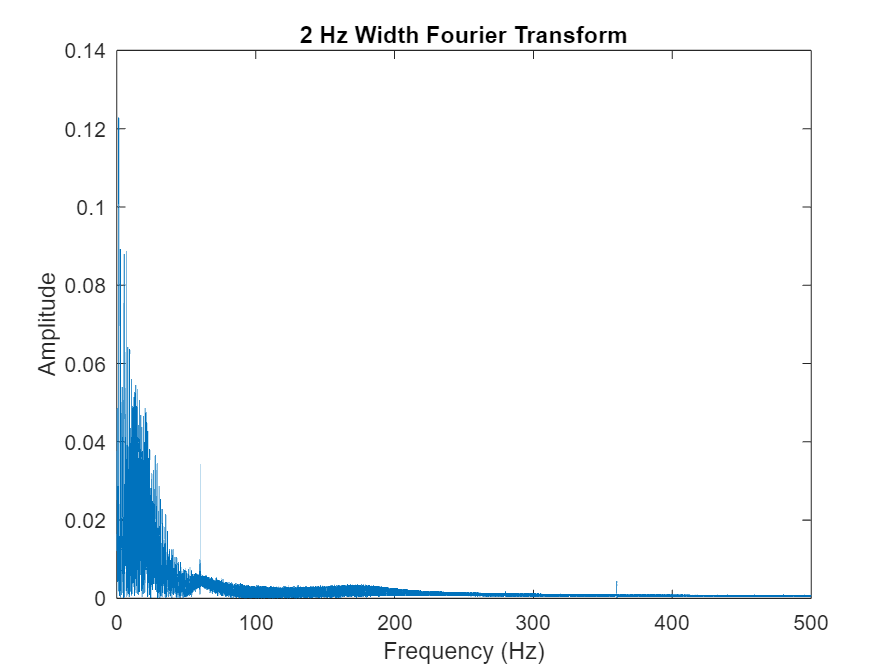

% Filter the signal
RLCStopFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(RLCStopFilteredSignal,fs)
title('2 Hz Width Fourier Transform')
hold off

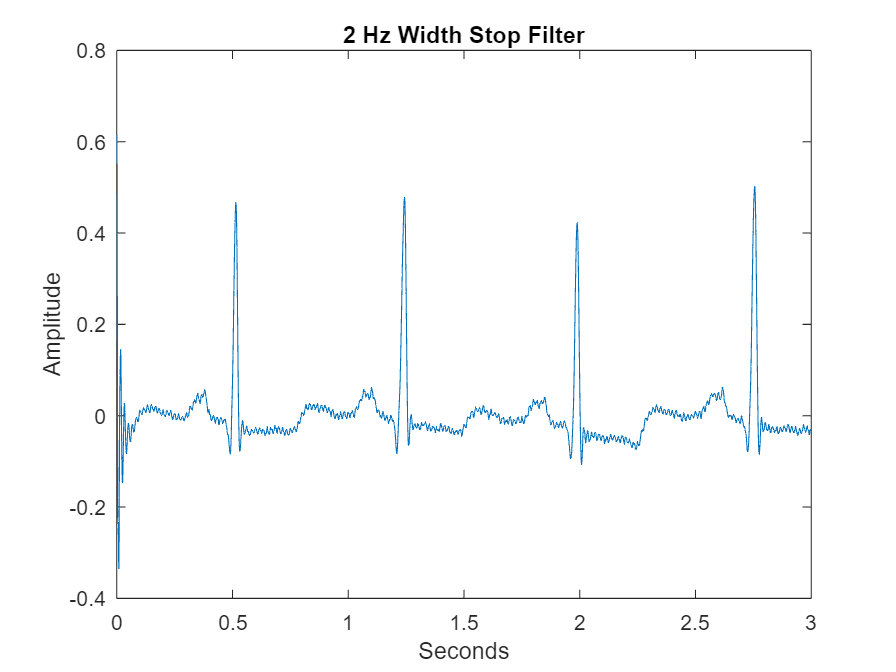

% Plot the filtered signal
plot(t,RLCStopFilteredSignal)
xlim([0,3])
title('2 Hz Width Stop Filter')
xlabel('Seconds')
ylabel('Amplitude')
hold off

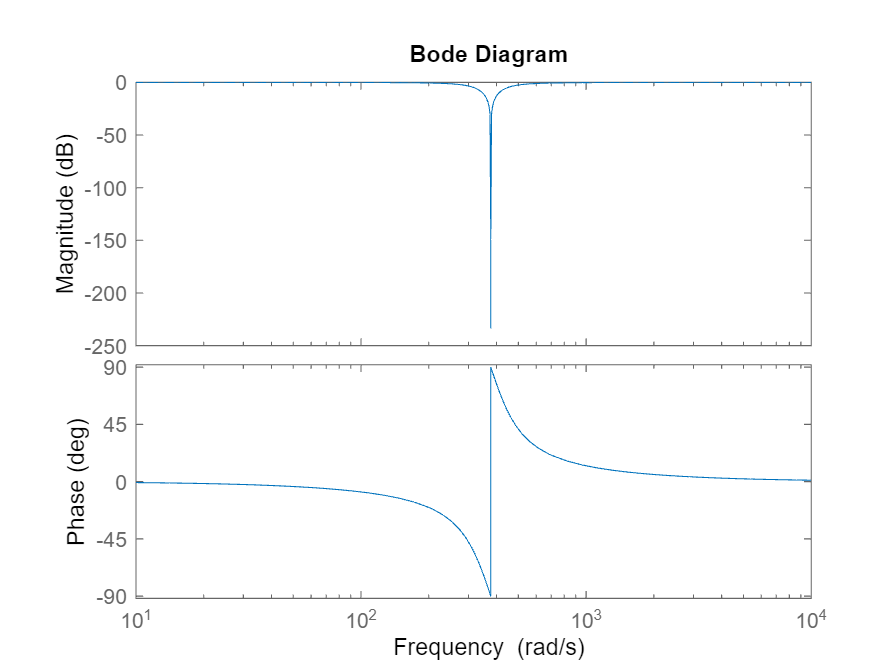

%% 3 Hz Width Stop Filter
% Load component values
R = 3*2*pi;
L = 1;
C = 1/((120*pi)^2);
syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vout = simplify(((Zl+Zc))/(Zr+Zl+Zc));
Hf = tf([L/((1/C)) 0 1],[L/((1/C)) (R*10)/((1/C)) 1]);
bodeplot(Hf)

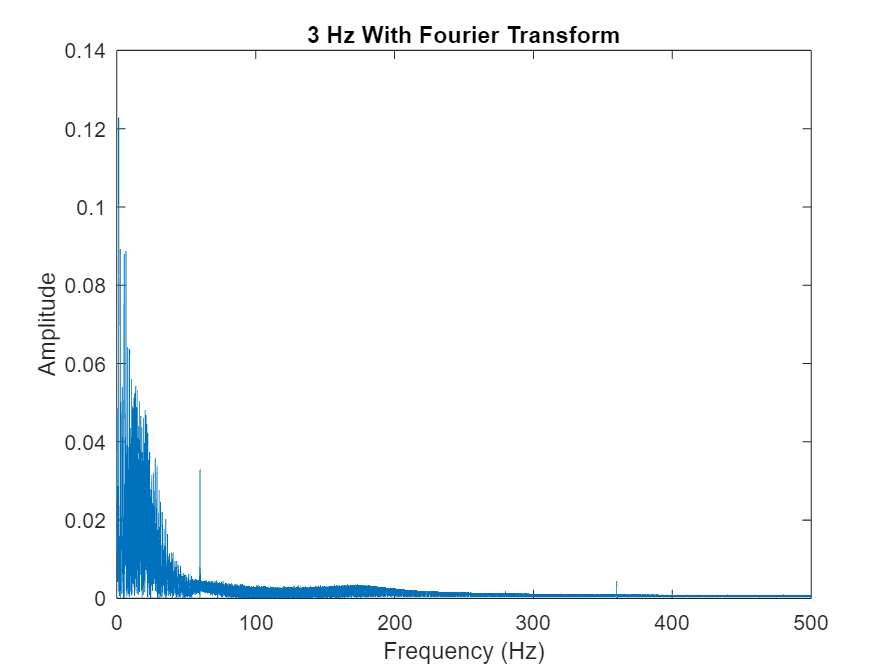

% Filter the signal
RLCStopFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(RLCStopFilteredSignal,fs)
title('3 Hz With Fourier Transform')
hold off

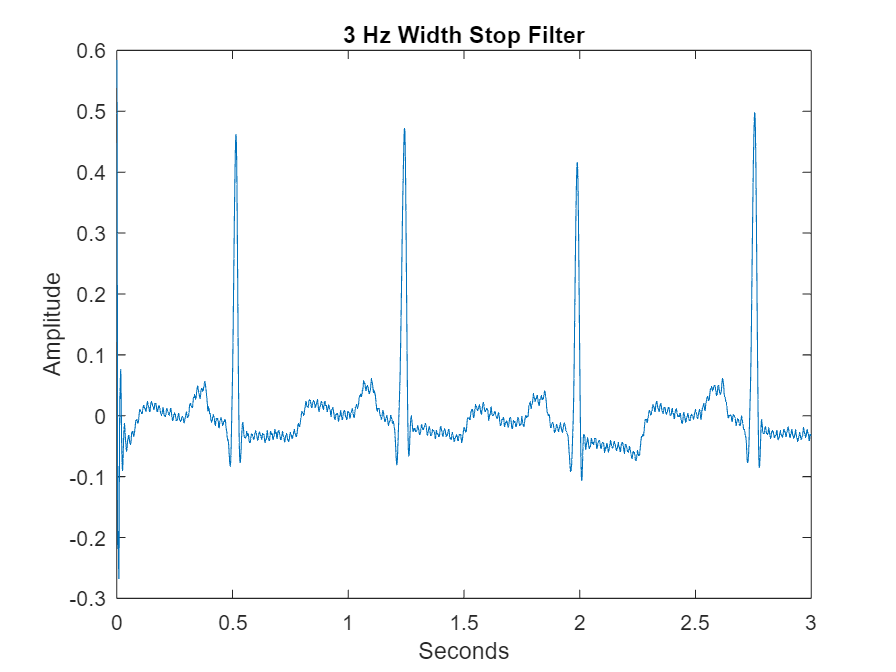

% Plot the filtered signal
plot(t,RLCStopFilteredSignal)
xlim([0,3])
title('3 Hz Width Stop Filter')
xlabel('Seconds')
ylabel('Amplitude')
hold off

### Butter Filter

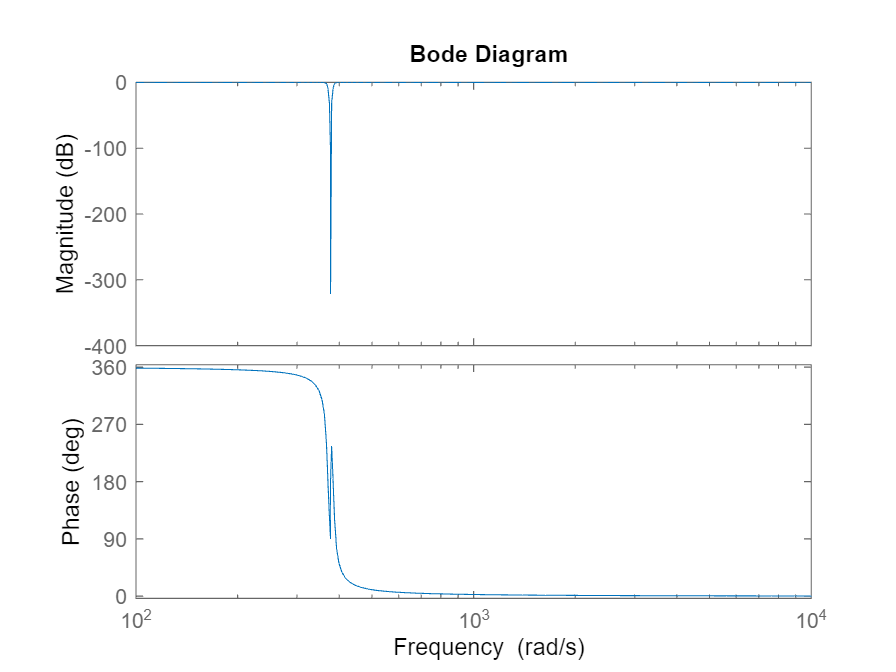

% Find the transfer function with 1.5 Hz Width
[num,den] = butter(3,[2*pi*58.5 2*pi*61.5],'stop','s');
Hf = tf(num,den);
% Plot the bode
bodeplot(Hf)

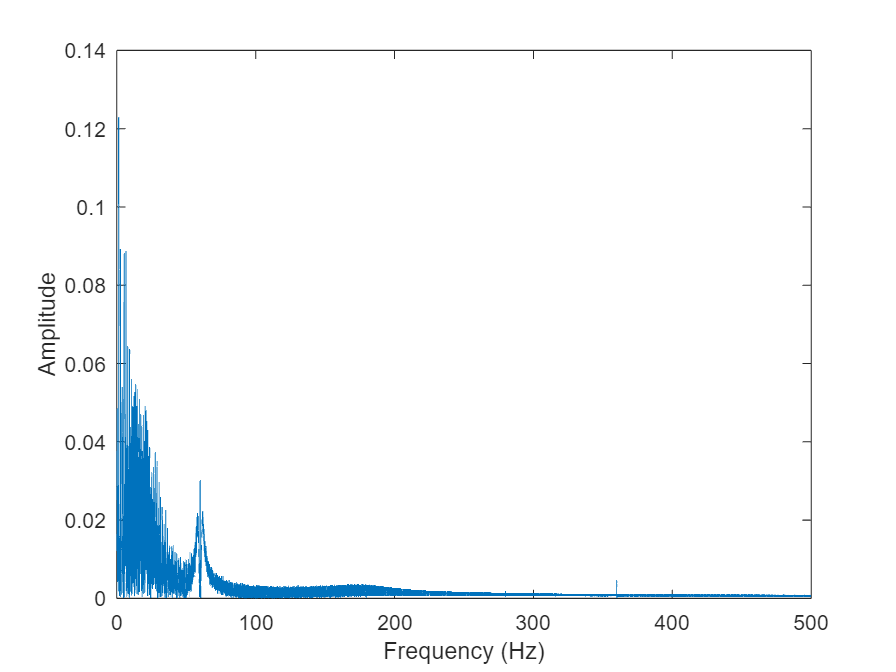

% Filter the signal
ButterFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(ButterFilteredSignal,fs)
hold off

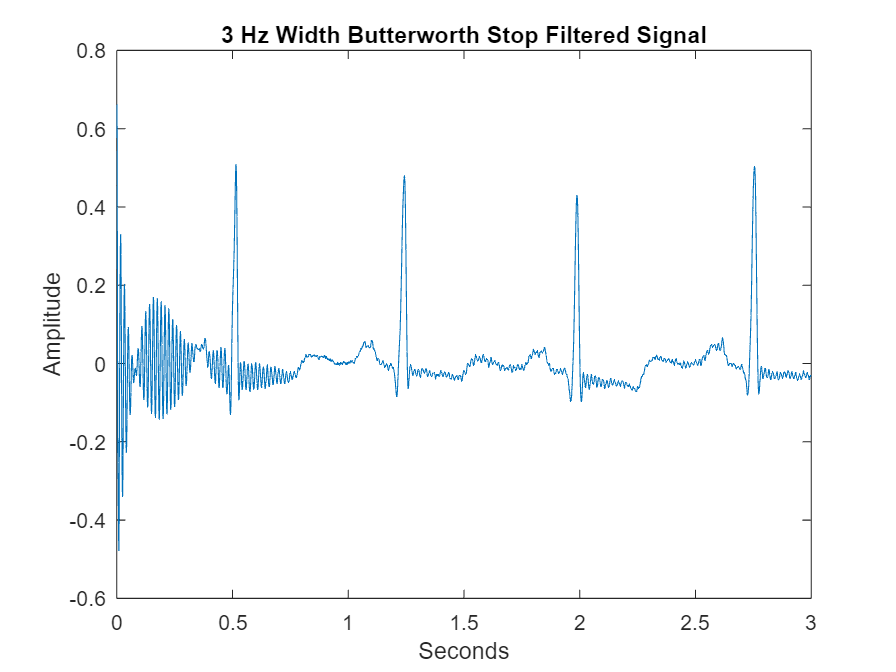

% Plot the filtered signal
plot(t,ButterFilteredSignal)
title('3 Hz Width Butterworth Stop Filtered Signal')
xlim([0 3])
xlabel('Seconds')
ylabel('Amplitude')
hold off

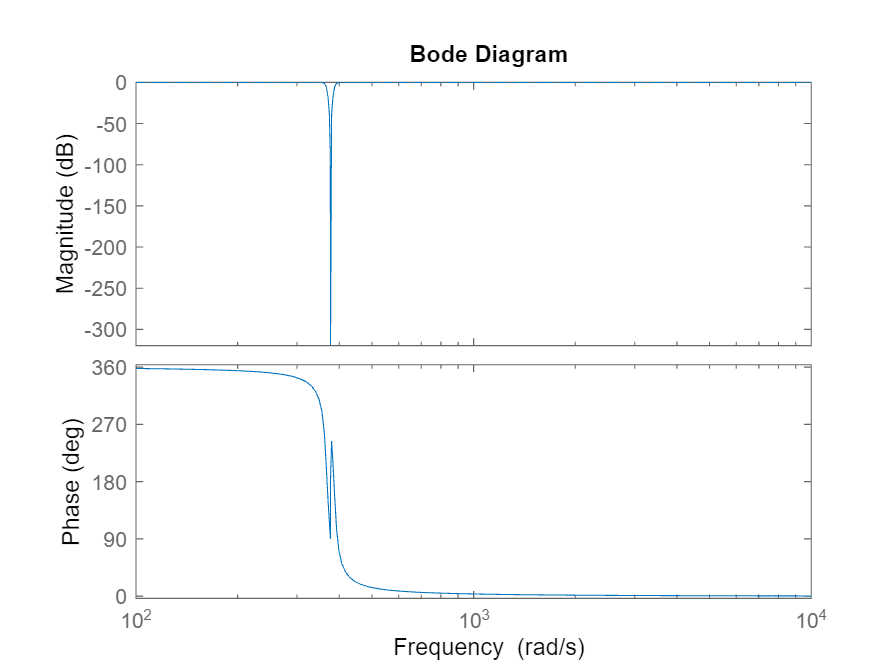

% Find the transfer function with 2 Hz Width
[num,den] = butter(3,[2*pi*58 2*pi*62],'stop','s');
Hf = tf(num,den);
% Plot the bode
bodeplot(Hf)

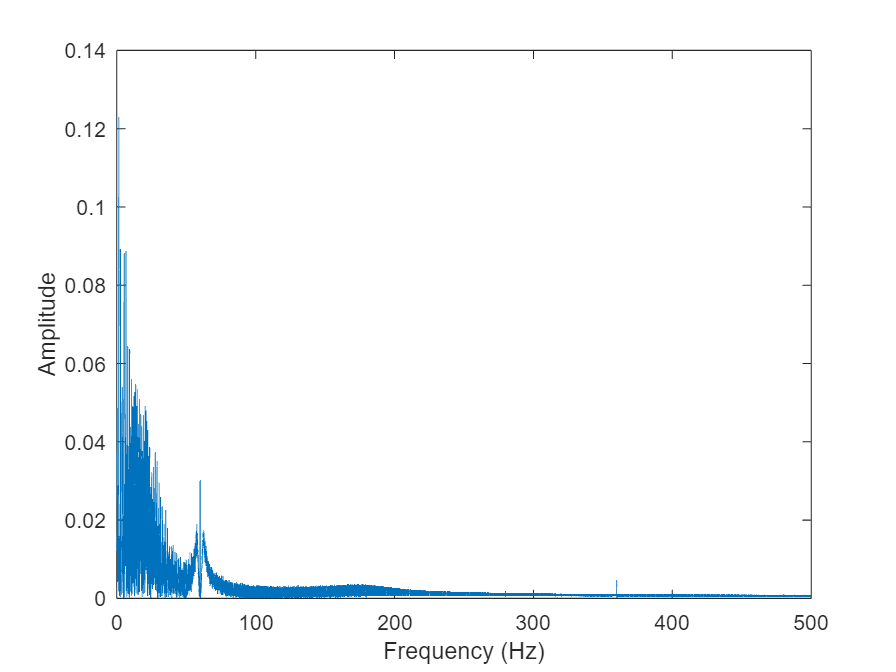

% Filter the signal
ButterFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(ButterFilteredSignal,fs)
hold off

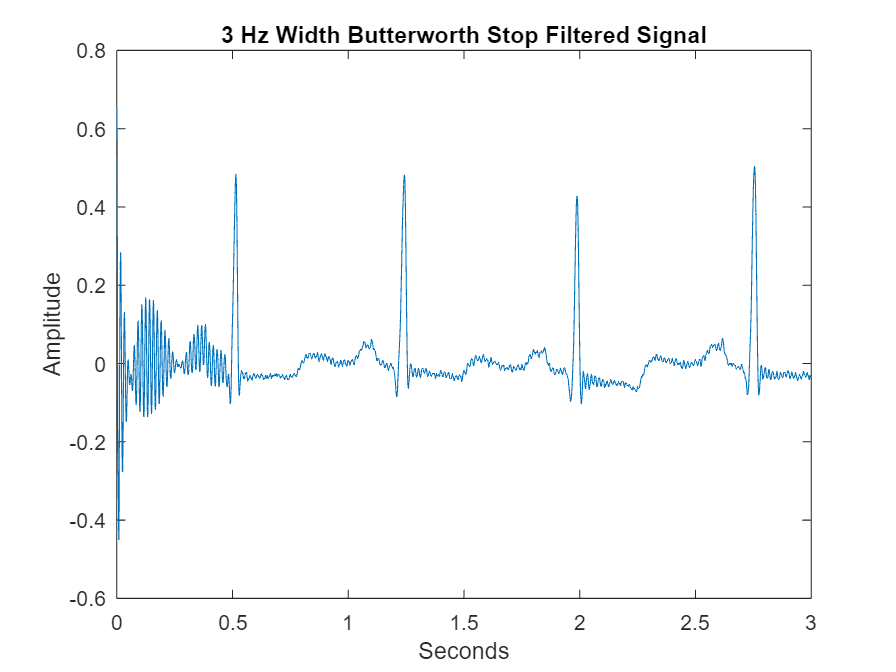

% Plot the filtered signal
plot(t,ButterFilteredSignal)
title('3 Hz Width Butterworth Stop Filtered Signal')
xlim([0 3])
xlabel('Seconds')
ylabel('Amplitude')
hold off

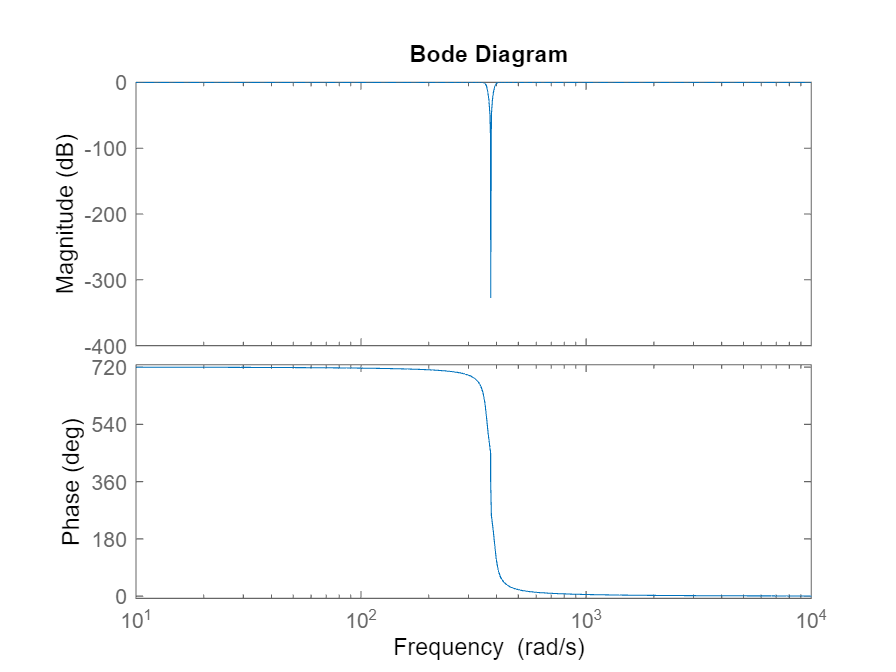

% Find the transfer function with 3 Hz Width
[num,den] = butter(3,[2*pi*57 2*pi*63],'stop','s');
Hf = tf(num,den);
% Plot the bode
bodeplot(Hf)

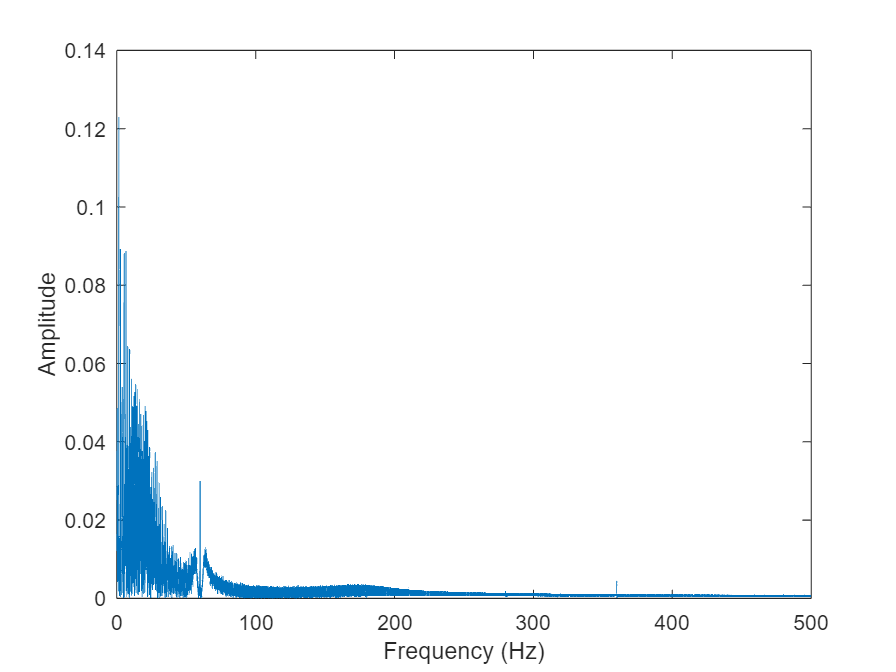

% Filter the signal
ButterFilteredSignal = lsim(Hf,x,t);
% Examine the fourier transform post filtering
myFFT(ButterFilteredSignal,fs)
hold off

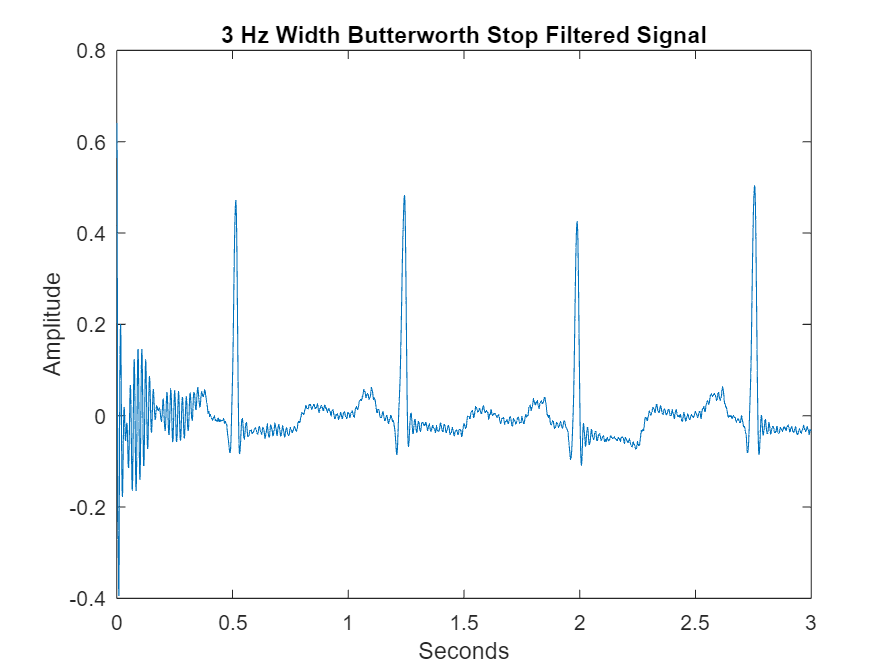

% Plot the filtered signal
plot(t,ButterFilteredSignal)
title('3 Hz Width Butterworth Stop Filtered Signal')
xlim([0 3])
xlabel('Seconds')
ylabel('Amplitude')
hold off